# Lab 5 - MATLAB Loops

## For Loop Example

for n = 3:10
    r(n)=rank(magic(n));
end
disp(r);

  Columns 1 through 14

     1     4     3     3     5     5     7     3     9     7    11     3    13     9

  Column 15

    15



Explain why the first two elements of the computed r vector are 0: The array index for n starts at 3 instead of 1, so the first two elements are 0.

## While Loop Example

n=3;
a=0;
while a < 15
    a = rank(magic(n));
    r(n)=a;
    n=n+1;
end
disp(r);

  Columns 1 through 14

     1     4     3     3     5     5     7     3     9     7    11     3    13     9

  Column 15

    15



Explain why the vector r has the number of elements it does: The while loop runs while a is less than 15. Because a starts at 0, there will be 15 elements created while the loop runs when a is less than 15.

## Nested Loops - Storing in an Array

for n=1:10
    for m=1:5
        H(n,m)=1/(n+m);
    end
end
disp(H);

    0.5000    0.3333    0.2500    0.2000    0.1667
    0.3333    0.2500    0.2000    0.1667    0.1429
    0.2500    0.2000    0.1667    0.1429    0.1250
    0.2000    0.1667    0.1429    0.1250    0.1111
    0.1667    0.1429    0.1250    0.1111    0.1000
    0.1429    0.1250    0.1111    0.1000    0.0909
    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1000    0.0909    0.0833    0.0769    0.0714
    0.0909    0.0833    0.0769    0.0714    0.0667



## Nested Loops - Inner Loop Depends on Outer Loop

for n=1:5
    a=1;
    for m=1:n
        a=a*(m^n);
    end
    r(n)=a;
end
disp(r);

   1.0e+10 *

  Columns 1 through 8

    0.0000    0.0000    0.0000    0.0000    2.4883    0.0000    0.0000    0.0000

  Columns 9 through 15

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



## Conditional Function Test

arr1 = input('Input first array(with []): ');
arr2 = input('Input second array(with []): ');
disp(arr1);

     1     2     3     4



disp(arr2);

     3     9     3     1




[dispArr1, dispArr2] = ConditionalFunction(arr1,arr2); 
%function explained below

ConditionalFunction checks the conditions of the two input arrays. If the values in Arr1 are less than 3, Arr1 is returned with its regular values and Arr2 is returned with a 0 vector. Otherwise, if the exclusive or between Arr1 and Arr2 results in any 1s, then Arr1 is returned as a 0 vector and Arr2 is returned as the exclusive or of the two input arrays. If neither condition is met, the the input arrays are returned as swapped. 

## Error Function Test

inX = input('Input x as zero or greater for no error: ');
disp(inX);

     1



y = ErrorFunction(inX);
%function explained below

ErrorFunction returns an error message if the input variable is less than 0. If no error message is returned, then the function returns a y value of 10.

## Resistor Ladder Fixed

inRs = input('Input array for Rs: ');
inRp = input('Input array for Rp: ');
disp(inRs);

     3     2     3



disp(inRp);

     4     3     1




[R] = R_Ladder_Fixed(inRs,inRp);
disp(R);

     3



%function explained below

R_Ladder_Fixed takes two input arrays for resistance values to compute the equivalent resistance of a fixed resistance ladder. The function also returns error messages if the input arrays for resistance values are unequal in size or if there are any negative values in the input arrays.

## Resistor Ladder Infinite

inR = input('Input resistance value for circuit: ');
inAlpha = input('Input change threshold: ');
inN = input('Input max number of loop iteration: ');
disp(inR);

     3



disp(inAlpha);

   1.0000e-04



disp(inN);

    20



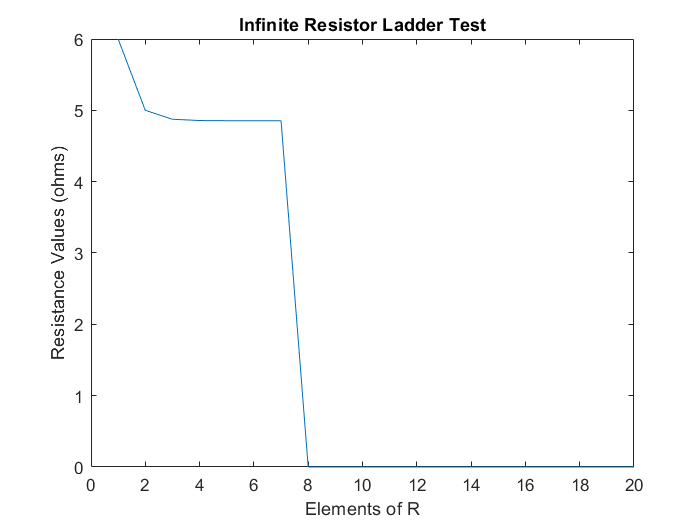


[arrR] = R_Ladder_Inf(inR, inAlpha, inN);
figure
plot(arrR)
xlabel('Elements of R')
ylabel('Resistance Values (ohms)')
title('Infinite Resistor Ladder Test')


%function explained below

R_Ladder_Inf returns the values of R for each stage of the ladder computed. The function takes a single resistance value for all resistors, a value for change threshold, and a max number of loops to perform. The function also returns an error message if any of the input values are less than or zero.